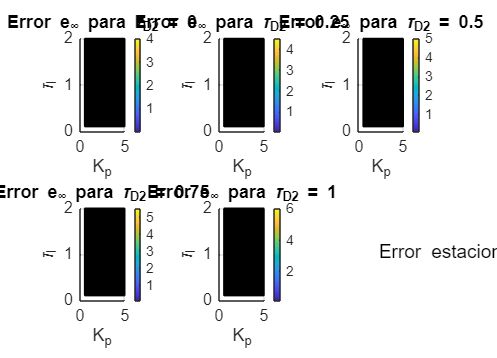

%% BLOQUE 1 - tau_D como variable de corte
close all;
clear;
clc;

% Parámetros constantes
K = 1;
p = 1;

% Rangos de variables
Kp_vals = linspace(0.5, 5, 30);
tauI_vals = linspace(0.1, 2, 30);
tauD_vals = linspace(0, 1, 5);  % Cortes para varias curvas/superficies

% Crear malla para Kp y tauI
[KP, TI] = meshgrid(Kp_vals, tauI_vals);

% Graficar superficies para distintos tauD
figure('Units', 'centimeters', 'Position', [2 2 25 18]);
for i = 1:length(tauD_vals)
    tauD = tauD_vals(i);

    % NUEVA fórmula
    E_inf = TI .* (p ./ (K * KP) + tauD);

    % Subplot
    subplot(2, 3, i);
    surf(Kp_vals, tauI_vals, E_inf);
    title(['Error e_{\infty} para \tau_{D2} = ', num2str(tauD)], 'FontSize', 13);
    xlabel('K_p'); ylabel('\tau_I'); zlabel('e_{\infty}');
    view(2); colorbar;
    set(gca, 'FontSize', 12);
end

subplot(2,3,6);
axis off;
text(0.2, 0.5, 'Error estacionario ante parábola para distintos \tau_{D2}', 'FontSize', 14);

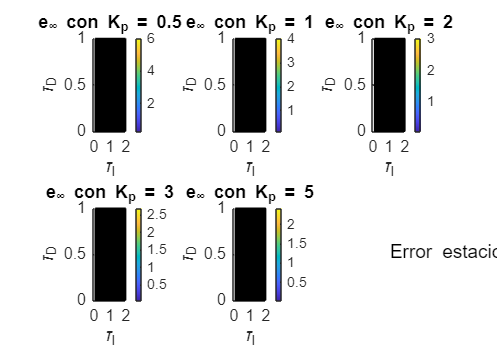


%% BLOQUE 2 - Variar Kp con tauI y tauD
close all;
clc;

% Constantes
K = 1;
p = 1;

% Rangos de tauI y tauD
tauI_vals = linspace(0.1, 2, 50);
tauD_vals = linspace(0, 1, 50);
[TI, TD] = meshgrid(tauI_vals, tauD_vals);

% Valores de Kp a analizar
Kp_vals = [0.5, 1, 2, 3, 5];

figure('Units', 'centimeters', 'Position', [2 2 25 18]);

for i = 1:length(Kp_vals)
    Kp = Kp_vals(i);

    % NUEVA fórmula
    E_inf = TI .* (p / (K * Kp) + TD);

    % Subplot
    subplot(2, 3, i);
    surf(tauI_vals, tauD_vals, E_inf);
    view(2);
    title(['e_{\infty} con K_p = ' num2str(Kp)], 'FontSize', 13);
    xlabel('\tau_I'); ylabel('\tau_D'); zlabel('e_{\infty}');
    colorbar;
    set(gca, 'FontSize', 12);
end

subplot(2,3,6);
axis off;
text(0.2, 0.5, 'Error estacionario ante parábola para distintos K_p', 'FontSize', 14);

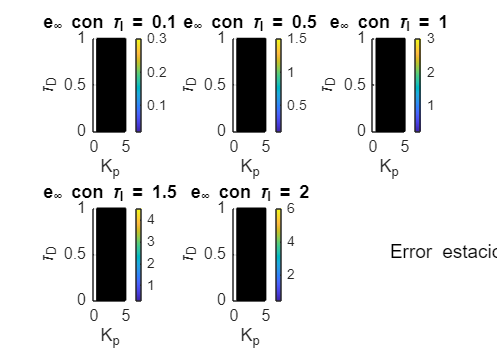


%% BLOQUE 3 - Variar tauI con Kp y tauD
close all;
clc;

% Constantes
K = 1;
p = 1;

% Rangos de Kp y tauD
Kp_vals = linspace(0.5, 5, 50);
tauD_vals = linspace(0, 1, 50);
[KP, TD] = meshgrid(Kp_vals, tauD_vals);

% Valores de tau_I a explorar
tauI_vals = [0.1, 0.5, 1, 1.5, 2];

figure('Units', 'centimeters', 'Position', [2 2 25 18]);

for i = 1:length(tauI_vals)
    tauI = tauI_vals(i);

    % NUEVA fórmula
    E_inf = tauI * (p ./ (K * KP) + TD);

    % Subplot
    subplot(2, 3, i);
    surf(Kp_vals, tauD_vals, E_inf);
    view(2);
    title(['e_{\infty} con \tau_I = ' num2str(tauI)], 'FontSize', 13);
    xlabel('K_p'); ylabel('\tau_D'); zlabel('e_{\infty}');
    colorbar;
    set(gca, 'FontSize', 12);
end

subplot(2,3,6);
axis off;
text(0.2, 0.5, 'Error estacionario ante parábola para distintos \tau_I', 'FontSize', 14);